# **MACHINE LEARNING REVISION**

**   Dai Tran - 6/18/2020**

## **Topic 1: Optimization problems**

### 1. Explaination

- fminsearch: [https://www.mathworks.com/help/optim/ug/fminsearch.html](https://www.mathworks.com/help/optim/ug/fminsearch.html)

- fmincon: [https://www.mathworks.com/help/optim/ug/fmincon.html](https://www.mathworks.com/help/optim/ug/fmincon.html)

Using **fmin **and **fmincon** to solve the optimization problem.

These folowing example explain the way we implement the optimization problem in Matlab.

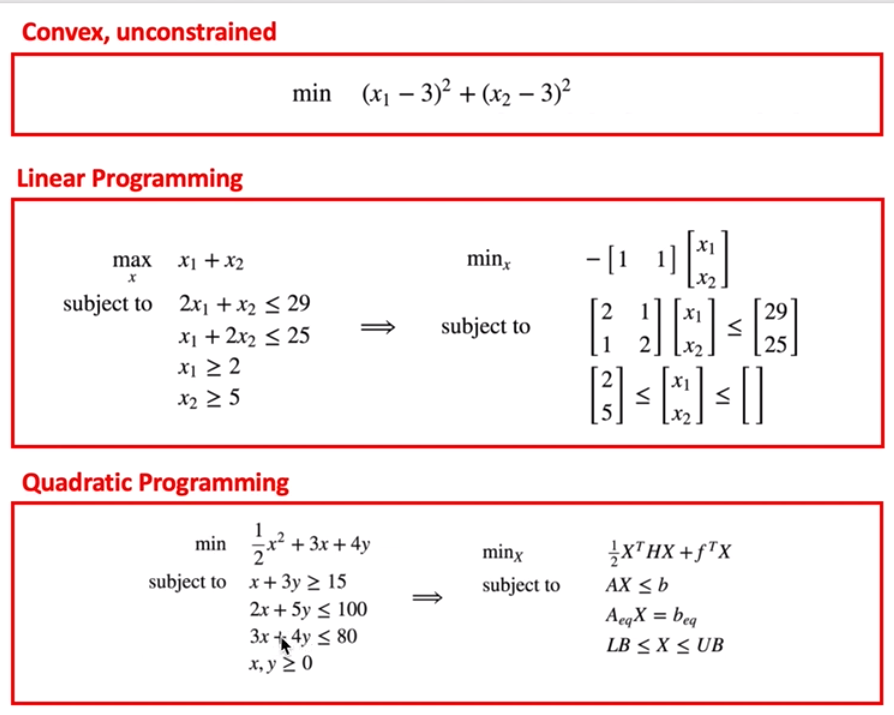

clearvars;close all;clc;

% Convex, unconstrained
options = optimset('PlotFcns',@optimplotfval); % monitor fminsearch
func = @(x)(x(1)-3)^2 + (x(2)-3)^2;
x0 = [ 2, 1];

disp('Optimal results of convex, unconstrained problem using fminsearch')

Optimal results of convex, unconstrained problem using fminsearch


% x1 = fminsearch(func,x0,options)
x1 = fminsearch(func,x0)

x1 =     3.0000    3.0000


disp('Optimal results of convex, unconstrained problem using fmincon')

Optimal results of convex, unconstrained problem using fmincon


x2 = fmincon(func,x0,[],[],[],[])


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x2 =     3.0000    3.0000



% Linear programming
func = @(x) -x(1)-x(2); % change maximize problem to become minimize problem
% change the syntax to become Ax<=b
Ain = [2 1;
       1 2];
bin = [29;
       25];
% lower bound
lb = [2;5];
% initial x
x0 = [2,1];
disp('Optimal results of linear programming using fmincon')

Optimal results of linear programming using fmincon


x = fmincon(func,x0,Ain,bin,[],[],lb)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =    11.0000    7.0000


disp('Optimal results of linear programming using linprog')

Optimal results of linear programming using linprog


f = [-1 -1];
x = linprog(f,Ain,bin,[],[],lb,[])'


Optimal solution found.



x =     11     7


% Quadratic programming
func = @(x) (1/2)*x(1)^2+3*x(1)+4*x(2)

func = function_handle with value:
    @(x)(1/2)*x(1)^2+3*x(1)+4*x(2)


% change the syntax to become Ax<=b
A = [-1 -3;
    2 5;
    3 4];
b = [15;
    100;
    80];
% lower bound
lb = zeros(2,1);
% initial x
x0 = [2,1];
disp('Optimal results of quadratic programming using fmincon')

Optimal results of quadratic programming using fmincon


x = fmincon(func,x0,A,b,[],[],lb)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x = 	1.0e+-5 *

    0.3333    0.2500


disp('Optimal results of quadratic programming using quadprog')

Optimal results of quadratic programming using quadprog


### 2. Gradient descent implementation

clearvars;close all;clc;

disp('Visualize objective function')

Visualize objective function


func = @(x)(x(1)-3)^2 + (x(2)-3)^2;
[X, Y] =meshgrid(0:0.2:5, 0:0.2:5);
Z = (X-3).^2 + (Y-3).^2;
figure
surf(X,Y,Z);
title('3D visualization')

Then we need to caculate the partial derivative with x1 and x2

dfunc = @(x)[2*(x(1)-3) 2*(x(2)-3)]'; % We want to use as a column vector

From here we can implement Gradient descent.

iter = 10;
x = [2 1];
learning_rate = 0.1;
threshold = 1e-4;
n = 0;

when the gradient near 0 then we can get the optimal value. 

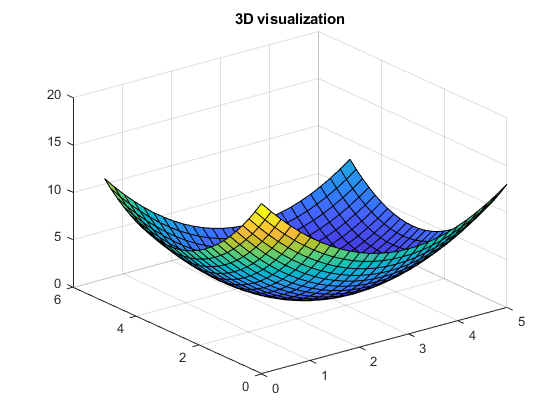

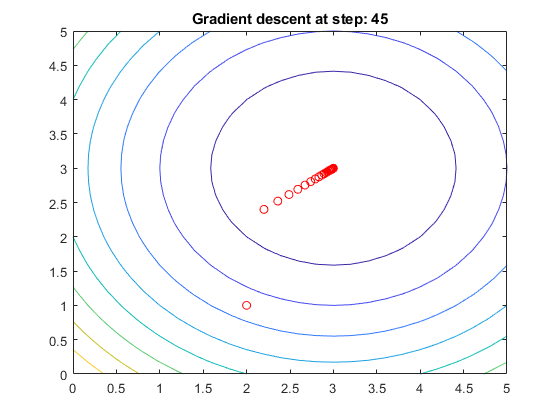

figure
contour(X,Y,Z);
view(0,90)
hold on
while norm(dfunc(x)) > threshold
    view(0,90)
    plot3(x(1),x(2),func(x),'ro')
    title(sprintf('Gradient descent at step: %g',n))
    x = x- learning_rate*dfunc(x);
    n = n + 1;
    drawnow
end

### 3. Example

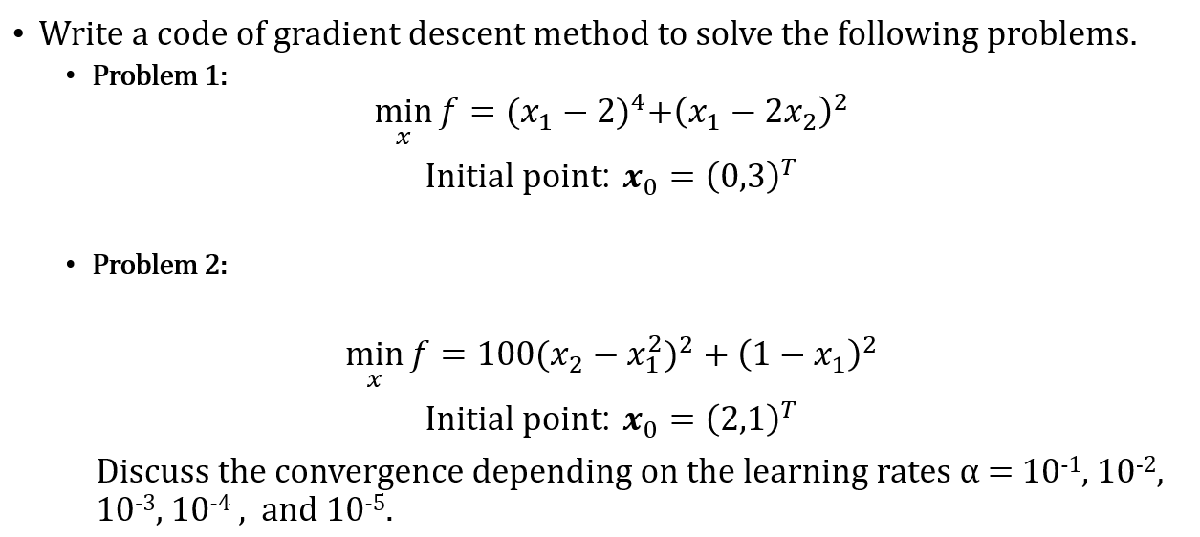

#### Problem 1

First, using fminsearch to find the optimal vaue

clearvars;close all;clc;
func = @(x)(x(1)-2)^2 + (x(1)-2*x(2))^2;
x0 = [0.3 0.3];
disp('Results of convex, unconstrained problem using fminsearch function');

Results of convex, unconstrained problem using fminsearch function


optimal_x = fminsearch(func, x0)

optimal_x =     2.0000    1.0000


Then implementing gradient descent, first taking differentiate w.r.t x1 and x2: **4*(x(1)-2)^3 + 2*x(1);   -4*x(1) + 8*x(2) ** 

dfunc = @(x)[4*(x(1)-2)^3+2*x(1)-4*x(2) -4*x(1)+8*x(2)]';
threshold = 1e-5;
learning_rate = 0.01;

Visualize results

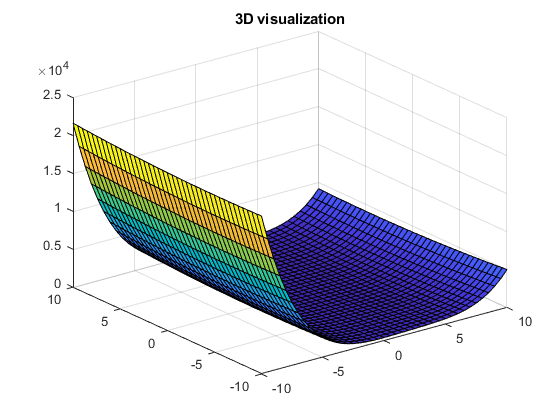

figure 
[X, Y] =meshgrid(-10:0.5:10, -10:0.5:10);
Z = (X-2).^4 + (X-2*Y).^2;
figure
surf(X,Y,Z);
title('3D visualization')
hold on

x = x0;
n = 0;
while norm(dfunc(x)) > threshold
    x = x - learning_rate*dfunc(x)';
%     plot3(x(1),x(2),func(x),'ro')
%     drawnow
    n = n+1;
end
disp('Results of convex, unconstrained problem using GD');

Results of convex, unconstrained problem using GD


x

x =     1.9859    0.9930


#### Problem 2

Similar with the first problem, first we need to take differenttiate w.r.t x1 and x2: **-400*(-x(1)^2+x(2))*x(1)-2+2*x(1)**; ** -200*x(1)^2+200*x(2)  **

clearvars;close all;clc;
func = @(x)100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
x0 = [2.1 2.1];
disp('Results of convex, unconstrained problem using fminsearch function');

Results of convex, unconstrained problem using fminsearch function


optimal_x = fminsearch(func, x0)

optimal_x =     1.0000    1.0000


figure 
[X, Y] =meshgrid(-10:0.2:10, -10:0.2:10);
Z = 100*(Y - X^2).^2 + (1-X).^2;
surf(X,Y,Z)

dfunc = @(x)[-400*(-x(1)^2+x(2))*x(1)-2+2*x(1) -200*x(1)^2+200*x(2)]';
threshold = 1e-5;
n= 0;
hold on 
for learning_rate = [10^-1 10^-2 10^-3 10^-4 10^-5]
    threshold = 1e-3;
    x = [2.1 2.1]';

    disp('============== Learning rate ==============')
    learning_rate 
    while norm(dfunc(x)) > threshold
        x = x - learning_rate*dfunc(x);
%         plot3(x(1),x(2),func(x),'ro')
%         drawnow
        n = n+1;
    end
    close all
    fprintf('Results of convex, unconstrained problem using GD with learning rat: %g\n',learning_rate);
    x'
    n
end

============== Learning rate ==============


learning_rate = 0.1000

Results of convex, unconstrained problem using GD with learning rat: 0.1


ans =    Inf   Inf


n = 6

============== Learning rate ==============


learning_rate = 0.0100

Results of convex, unconstrained problem using GD with learning rat: 0.01


ans =    NaN   Inf


n = 13

============== Learning rate ==============


learning_rate = 1.0000e-03

Results of convex, unconstrained problem using GD with learning rat: 0.001


ans =     1.0011    1.0022


n = 12251

============== Learning rate ==============


learning_rate = 1.0000e-04

Results of convex, unconstrained problem using GD with learning rat: 0.0001


ans =     1.0011    1.0022


n = 187868

============== Learning rate ==============


learning_rate = 1.0000e-05

Results of convex, unconstrained problem using GD with learning rat: 1e-05


ans =     1.0011    1.0022


n = 1945208

For the large alpha, the GD algorithm can not find the optimal solution for this problem, even

alpha =0.1 or 0.01; But when learning rate small enough (from 0.001), the GD algorithm give

us an optimal solution. From this conclusion, we need to take care the learning rate to give us

an approriate results  

## Topic 2: Regression

    Problem and solution

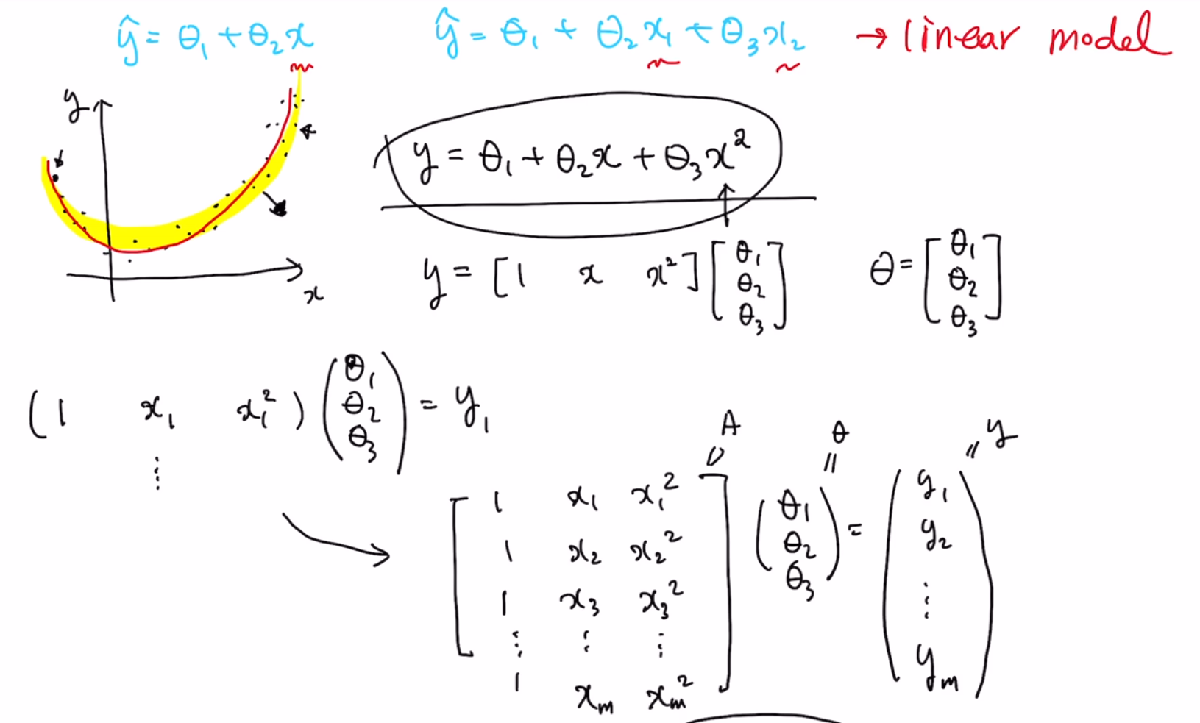

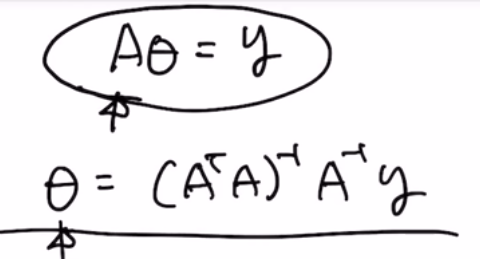

  **  Radial basis function (RBF)**

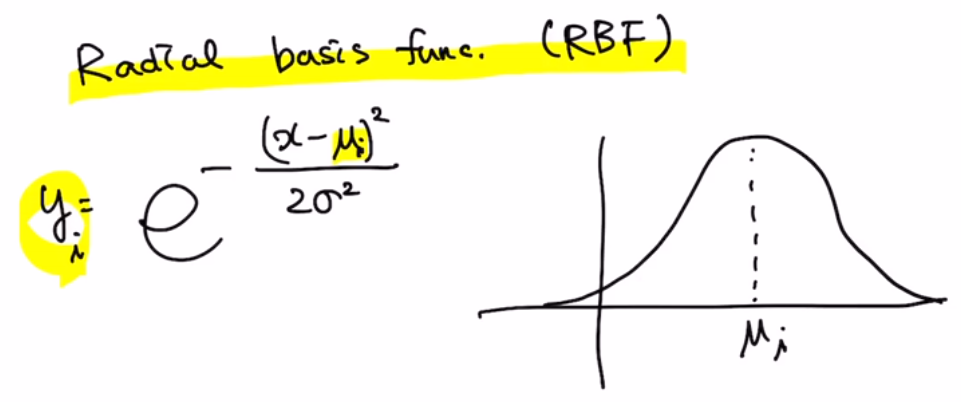

### 1. Multivarate linear regression using least square solution

clearvars; close all;clc
% Multivarate linear regression
% Generate data set
npts = 300;
x1 = randn(npts, 1); 
% random number generation which follows normal distribution
% std = 1 and mean = 0
x2 = randn(npts, 1);

y = 2+x1 + 3*x2 -1 + randn(npts,1);
figure;
plot3(x1,x2,y,'xb')
title('Multivarate linear regression using least square solution')
grid minor
hold on

Implement linear regression using least square solution

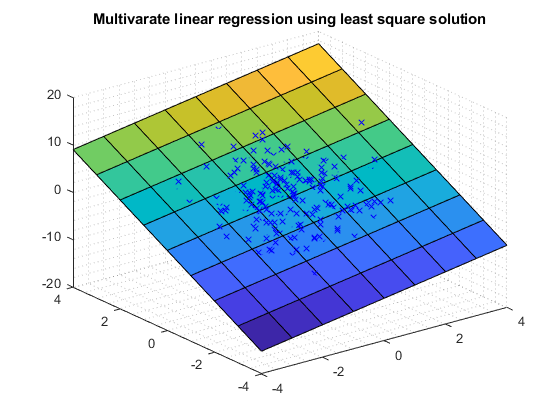

A = [ones(npts,1) x1 x2];
theta = inv(A'*A)*A'*y;
% Visualize 
[X Y] = meshgrid(-4:1:4,-4:1:4);
Z = theta(1) +theta(2)*X + theta(3)*Y;
surf(X,Y,Z,'EdgeColor','k')

% legend('Data','Fitting plane')

### **2. Implement non linear regression **

clearvars; close all;clc;
npts = 100;
x = 20*rand(npts,1) - 10;
y = 30 + 4*x +2*x.^2 + 10*randn(npts,1);

plot(x,y,'ro')
%  using least square solution

A = [ones(npts,1) x x.^2 x.^3 x.^4];
theta = inv(A'*A)*A'*y;

hold on
x_a = linspace(-10,10,1000);
y_a = theta(1) + theta(2)*x_a + theta(3)*x_a.^2 + ...
    theta(4)*x_a.^3 +theta(5)*x_a.^4;
disp('Non linear regression using least square solution')

Non linear regression using least square solution


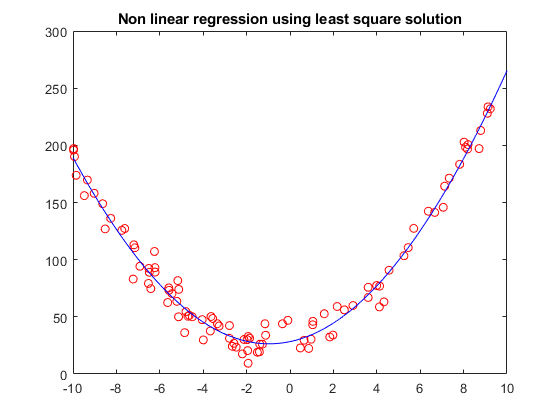

plot(x_a,y_a,'b-')
title('Non linear regression using least square solution')


% disp('Non linear regression using radial basis function')
% figure;
% plot(x,y,'ro')
% 
% sigma = 1;
% mu = linspace(-10,10,4);
% 
% rbf_1 = @(x) exp(-(x - mu(1))^2/(2*sigma^2));
% rbf_2 = @(x) exp(-(x - mu(2))^2/(2*sigma^2));
% rbf_3 = @(x) exp(-(x - mu(3))^2/(2*sigma^2));
% rbf_4 = @(x) exp(-(x - mu(4))^2/(2*sigma^2));
% 
% A = [];
% for i = 1:size(y,1)
%     A = [A; rbf_1(x(i)) rbf_2(x(i)) rbf_3(x(i)) rbf_4(x(i))];
% end
% theta = zeros(4,1);
% func = @(theta)norm(A*theta-y)^2;
% % options = optimset('MaxFunEvals',10000);
% theta_opt = fminsearch(func, 10.*ones(size(y,1),1))
% 
% hold on
% 
% for i = 1:length(xa)
%     yv2(i) = [rbf_1(xa(i)) rbf_2(xa(i)) rbf_3(xa(i)) rbf_4(xa(i))]*theta_opt;
% end
% 
% plot(xa,yv2)


### **2. Overfitting cases**

clearvars; close all;clc;
x = linspace(-4.5,4.5,10)';
y = [0.9819 0.7973 1.937 0.1838 1.3180 -0.8361 -0.6591 -2.4701 -2.1822 -6.2512]';
plot(x,y,'bo')
hold on

Try linear regression with the above examplie

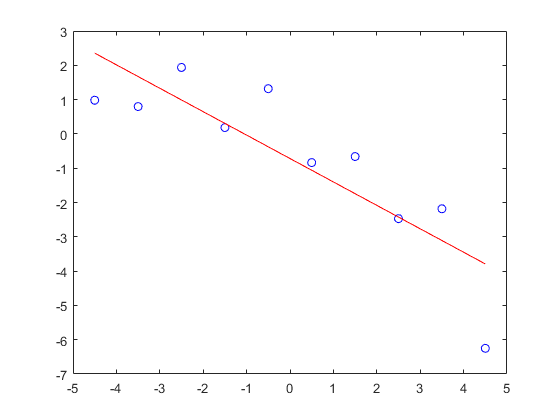

A = [ones(10,1) x];
theta = inv(A'*A)*A'*y;
xa = linspace(-4.5,4.5,100);
ya = theta(1) + theta(2).*xa;
plot(xa,ya,'r-')

Try RBF (polynomial regression)

sigma = 1;
mu = linspace(-4.5,4.5,10);

rbf_1 = @(x) exp(-(x - mu(1))^2/(2*sigma^2));
rbf_2 = @(x) exp(-(x - mu(2))^2/(2*sigma^2));
rbf_3 = @(x) exp(-(x - mu(3))^2/(2*sigma^2));
rbf_4 = @(x) exp(-(x - mu(4))^2/(2*sigma^2));
rbf_5 = @(x) exp(-(x - mu(5))^2/(2*sigma^2));
rbf_6 = @(x) exp(-(x - mu(6))^2/(2*sigma^2));
rbf_7 = @(x) exp(-(x - mu(7))^2/(2*sigma^2));
rbf_8 = @(x) exp(-(x - mu(8))^2/(2*sigma^2));
rbf_9 = @(x) exp(-(x - mu(9))^2/(2*sigma^2));
rbf_10 = @(x) exp(-(x - mu(10))^2/(2*sigma^2));

A = [];
for i = 1:10
    A = [A; rbf_1(x(i)) rbf_2(x(i)) rbf_3(x(i)) rbf_4(x(i)) rbf_5(x(i)) rbf_6(x(i)) rbf_7(x(i)) rbf_8(x(i)) rbf_9(x(i)) rbf_10(x(i))];
end

func = @(theta)norm(A*theta-y)^2;
options = optimset('MaxFunEvals',10000);
theta_opt = fminsearch(func, 10*ones(10,1),options)

hold on

for i = 1:length(xa)
    yv2(i) = [rbf_1(xa(i)) rbf_2(xa(i)) rbf_3(xa(i)) rbf_4(xa(i)) rbf_5(xa(i)) rbf_6(xa(i)) rbf_7(xa(i)) rbf_8(xa(i)) rbf_9(xa(i)) rbf_10(xa(i))]*theta_opt;
end

plot(xa,yv2)

The reasion why our results is different: *"Your problem does not seem to be *[*convex*](http://en.wikipedia.org/wiki/Convex_function)*. This means *`fminsearch`* will find a local minimum rather than a global minimum, and thus your result will be dependent on your initial estimation. You can check this by altering your *`theta0`* value to for example - Which yields completely different results. One way of working around this problem is using a *[*Monte Carlo method*](http://en.wikipedia.org/wiki/Monte_Carlo_method)*, which basically means you run the simulation over and over again for different initial conditions and select the result that yields the largest function value (along with its optimization parameter set theta). The more simulations you run, the more likely you are to find the 'true' optimum, although this is not a guaranteed outcome." "Its seems like our optimization problem is not a convex type. So fminsearch find the local minimum instead. *

### 3. Regularization

Add regularization term in cost function.

lambda = 0.5;

func = @(theta)norm(A*theta-y)^2 + lambda*norm(theta)^2;
options = optimset('MaxFunEvals',10000);
theta_opt = fminsearch(func, 10*ones(10,1),options)

hold on

for i = 1:length(xa)
    yv2(i) = [rbf_1(xa(i)) rbf_2(xa(i)) rbf_3(xa(i)) rbf_4(xa(i)) rbf_5(xa(i)) rbf_6(xa(i)) rbf_7(xa(i)) rbf_8(xa(i)) rbf_9(xa(i)) rbf_10(xa(i))]*theta_opt;
end

plot(xa,yv2,'b')
legend('Data point','Using linear regression','Using 10 RBFs', 'Using 10 RBFs with regularization term')

### 4. Assignment 2

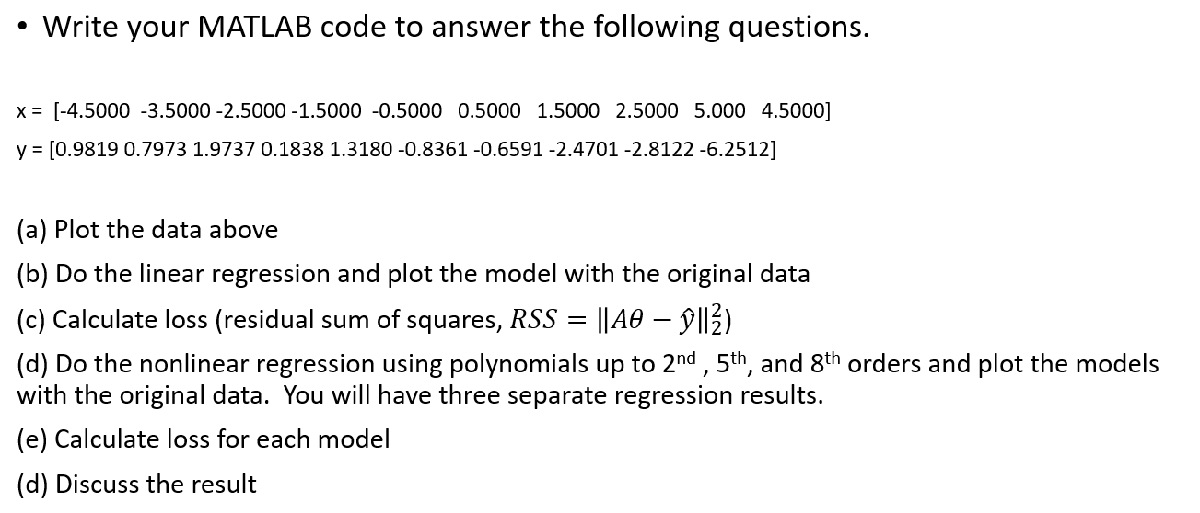

clearvars;close all;clc;
x = linspace(-4.5,4.5,10);
xa = linspace(-4.5,4.5,1000);
y = [0.9819 0.7973 1.9737 0.1838 1.3180 -0.8361 -0.6591 -2.4701 -2.8122 -6.2512];
% (a)
plot(x,y,'bo');
% (b)
A1 = [ones(10,1) x'];
theta1 = inv(A1'*A1)*A1'*y';
hold on 
ya1 = theta1(1) + theta1(2)*xa;
% (c)
RSS1 = norm(A1*theta1 - ya1)^2

RSS1 = 4.1671e+04

% (d)
A2 = [ones(10,1) x' x'.^2];
theta2 = inv(A2'*A2)*A2'*y';
ya2 = theta2(1) + theta2(2)*xa + theta2(3).*xa.^2;
RSS2 = norm(A2*theta2 - ya2)^2

RSS2 = 5.3050e+04


A5 = [ones(10,1) x' x'.^2 x'.^3 x'.^4 x'.^5];
theta5 = inv(A5'*A5)*A5'*y';
ya5 = theta5(1) + theta5(2)*xa + theta5(3).*xa.^2 + theta5(4).*xa.^3 + theta5(5).*xa.^4 + theta5(6).*xa.^5;
RSS5 = norm(A5*theta5 - ya5)^2

RSS5 = 5.4124e+04


A8 = [ones(10,1) x' x'.^2 x'.^3 x'.^4 x'.^5 x'.^6 x'.^7 x'.^8];
theta8 = inv(A8'*A8)*A8'*y';
ya8 = theta8(1) + theta8(2)*xa + theta8(3).*xa.^2 + theta8(4).*xa.^3 + theta8(5).*xa.^4 + theta8(6).*xa.^5 +theta8(7).*xa.^6 +theta8(8).*xa.^7+theta8(9).*xa.^8;
RSS8 = norm(A8*theta8 - ya8)^2

RSS8 = 5.3974e+04

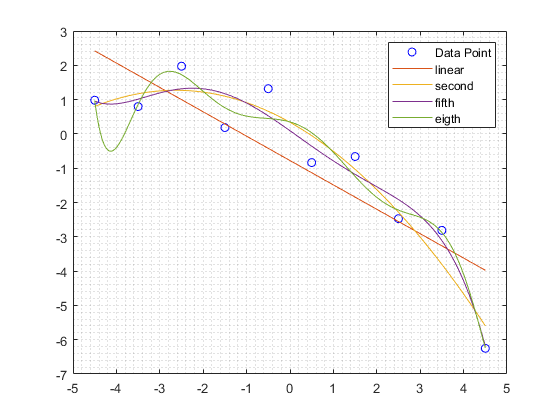


% RSS1 = norm(y - ya1)^2
% RSS2 = norm(y - ya2)^2
% RSS5 = norm(y - ya5)^2
% RSS8 = norm(y - ya8)^2

plot(xa,ya1);
plot(xa,ya2);
plot(xa,ya5);
plot(xa,ya8);
grid minor
legend('Data Point','linear','second','fifth','eigth');

As seen in the figure (d), the higher order of polynomial function, the fitter line we have. However,

in the real Ml/ DL applications, we can not base on only training data results. For example, in

the above toy data set, the 8th polynomial function can describe really fit to the data. But if we

generate more data for testing phase, the model may not perform a better results than the lower

one. Therefor, the only way to create a good model in ML/DL is "trial and error", keep training and

visualize the training and valiadation curve to choose the good model .

## Lecture 5: Classification using perceptron

### 1. Denoising using linear regresison

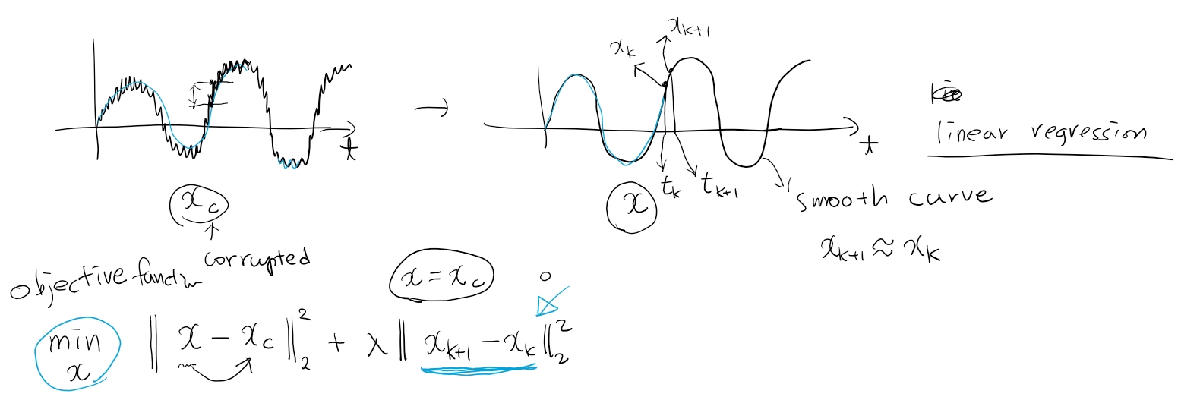

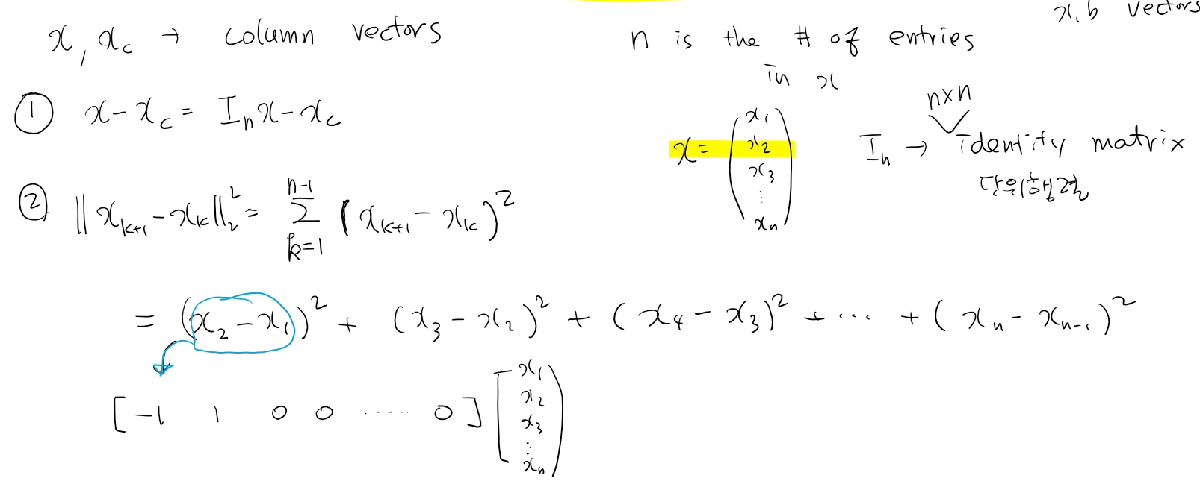

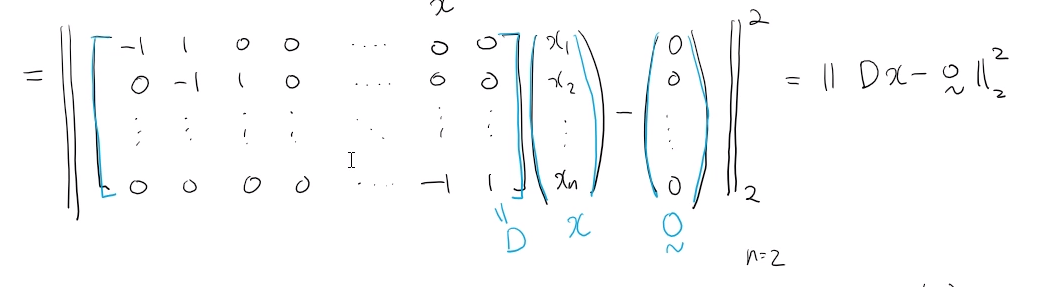

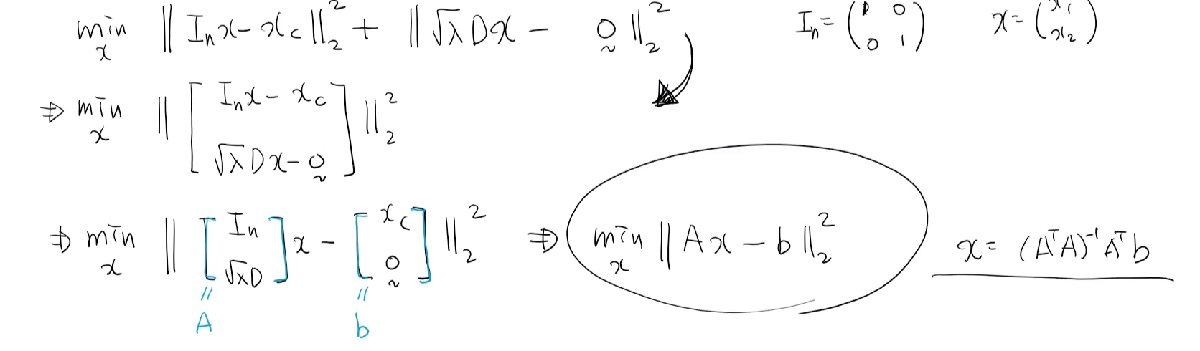

clearvars;close all;clc;
npts = 3000;
t = linspace(0,10,npts)';

xo = 0.5*sin(2*pi*t).*sin(2*pi*t/10);

xc = xo + 0.1*randn(size(xo));
plot(t,xo,'r.-','LineWidth',1)
hold on
plot(t,xc,'k--')
hold on
% solve using least square solution
lambda = 1000;

%  Create matrix D as presented above
D1 = zeros(npts-1,npts);
D2 = zeros(npts-1,npts);
D1(:,1:end-1) = -diag(ones(npts-1,1));
D2(:,2:end) = diag(ones(npts-1,1));
D = D1 + D2;

A = [eye(npts);
    sqrt(lambda)*D];
%  Create vector b
b = [xc;
    zeros(npts-1,1)];
% Caculate least square solution
xdenoising = (A'*A)\A'*b

xdenoising =     0.0333
    0.0332
    0.0332
    0.0331
    0.0332
    0.0333
    0.0335
    0.0337
    0.0338
    0.0340


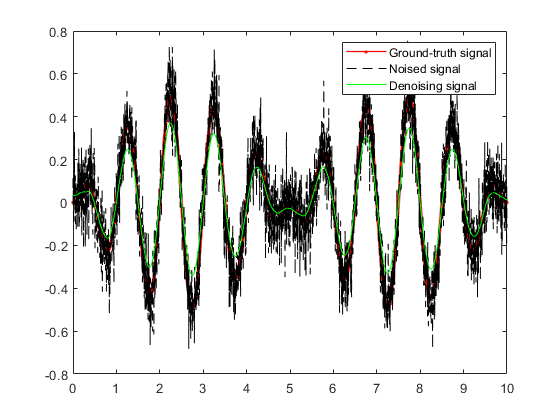

plot(t,xdenoising,'g')
legend('Ground-truth signal','Noised signal','Denoising signal')

### 2. Classification 

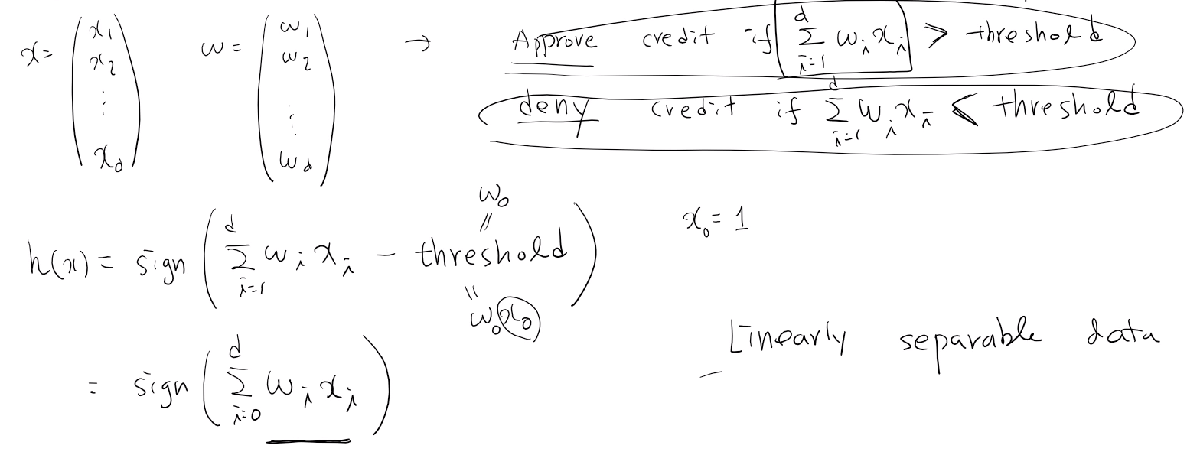

% Perceptron example
clearvars;close all;clc;
n = 10;
x1_1 = 5*rand(n,1) + 1;
x1_2 = 5*rand(n,1) - 1;

a = 0.8*x1_1 + x1_2 -3;
x2_1 = a -2;
x2_2 = a +2;
figure

plot(x1_1, x2_1, '.')
hold on
plot(x1_2, x2_2,'.')

xlabel('x_1');
ylabel('x_2');

% randomly select w
w = rand(3,1);
% normalize it
w = w/norm(w);
 
x = [ones(2*n,1) [x1_1; x1_2] [x2_1; x2_2]];
y = [ones(n,1); -ones(n,1)];

while 1
    g = x*w;
    wrong_classiifcation = find(g.*y < 0);
    % if right, then g and y will be have same sign. but if it wrong, then
    % they have different sign -> g.*y < 0
    if isempty(wrong_classiifcation)
        break;
    else
        % pick one wrong classification - > choose first 1
        idx = wrong_classiifcation(1);
    end
    w = w + y(idx)*x(idx)';
end

x1a = linspace(-1,6,100);
x2a = -w(2)/ w(3)*x1a - w(1)/w(3)

plot(x1a,x2a)

### 3. Assignment 3

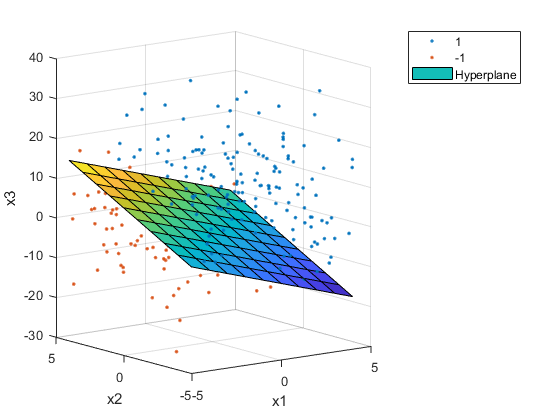

clear all; clc; close all
n = 300;
x1 = 10*rand(n,1) - 5;
x2 = 10*rand(n,1) - 5;
x3 = 10*randn(n,1) + 5;

idx = zeros(n,1);

for i=1:n
    g = 2*x1(i) -3*x2(i) + x3(i);
    if g > 3
        idx(i) = 1;
    elseif g < -3
        idx(i) = -1;
    else
        idx(i) = 0;
    end
end
% -> unbalance dataset 
i = find(idx==1);
x11 = x1(i); x21 = x2(i); x31 = x3(i);
i = find(idx==-1);
x12 = x1(i); x22 = x2(i); x32 = x3(i);

% figure;
% 
plot3(x11,x21,x31,'.')
hold on
plot3(x12, x22, x32,'.')
grid on
xlabel('x1');
ylabel('x2');
zlabel('x3');
hold on 
% randomlize 2
% -> unbalance dataset 
w = randn(4,1) - 0.5;
w = w/norm(2);
size_data = size([x31; x32]);
size_1 = size(x11);
size_2 = size(x12);
x = [ones(size_data(1),1) [x11; x12] [x21; x22] [x31; x32]];
y = [ones(size_1(1),1); -ones(size_2(1),1)];
n=1;
while 1 
    g = x*w;
    % muliple wrong classification
    wrong_classifications = find(g.*y<0);
    if isempty(wrong_classifications)
        break;
    else
        idx = wrong_classifications(1);
    end
    w = w+y(idx)*x(idx,:)';
%     disp(w)
%     disp(n)
%     n = n+1;
end
% draw a plane
% plane function = ax +by+cz+d = 0
[xx, yy] = ndgrid(min(x1):max(x1),min(x2):max(x2));
z = (-w(2)*xx - w(3)*yy - w(4))/w(1);
surf(xx,yy,z)
legend('1','-1','Hyperplane');

### Lecture 6: Support vector machine

### 1. Implementation SVM from scratch

clearvars;close all;clc;
npts = 100;
x11 = 10*rand(npts,1) + 2;
x12 = 10*rand(npts,1) - 2;

a = 0.8*x11 + x12 -3;
x21 = a -4;
x22 = a +4;


x11(1) = 4;
x21(1) = 9;
x11(2) = 6;
x21(2) = 7;
x11(1) = 3;
x21(1) = 5;

figure

plot(x11, x21, '.')
hold on
plot(x12, x22,'.')

xlabel('x1');
ylabel('x2');

X1 = [ones(npts,1) x11 x21];
X2 = [ones(npts,1) x12 x22];

A = [[-X1; X2] -eye(2*npts)
    zeros(2*npts,3) -eye(2*npts)];

b = [-ones(2*npts,1)
    zeros(2*npts,1)];

gamma = 1;
func = @(x)gamma*sum(x(4:end)) + norm(x(1:3));

x0 = rand(2*npts + 3,1);

options = optimoptions('fmincon');
% increase the iteration
options.MaxFunctionEvaluations = 3e5;
x = fmincon(func,x0,A,b,[],[],[],[],[],options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



x1a = -2:1:12;
w0 = x(1);
w1 = x(2);
w2 = x(3);

x2a = -w1/w2*x1a - w0/w2;
hold on
% prove it!!!!
plot(x1a,x2a,'r-') %g(x) = 0 line
plot(x1a,x2a + 1/w2,'r-') %g(x) = 1 line
plot(x1a,x2a - 1/w2,'r-') %g(x) = -1 line

### 2. Implementation with Matlab function

X = [x11 x21
    x12 x22];
Y = [ones(npts,1)
    -ones(npts,1)];

SVMModel = fitcsvm(X,Y);

sv = SVMModel.SupportVectors;
% figure
gscatter(X(:,1), X(:,2), Y)
hold on

plot(sv(:,1), sv(:,2),'o')


### 3. Classifying nonlinear separable data

### 4. Assignment 4

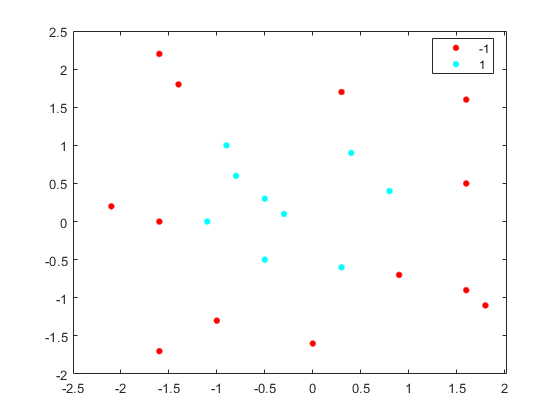

clearvars; clc; close all
% data
X1 = [ -1.1 0
-0.3 0.1
-0.9 1
0.8 0.4
0.4 0.9
0.3 -0.6
-0.5 0.3
-0.8 0.6
-0.5 -0.5];
X2 = [ -1 -1.3
-1.6 2.2
0.9 -0.7
1.6 0.5
1.8 -1.1
1.6 1.6
-1.6 -1.7
-1.4 1.8
1.6 -0.9
0 -1.6
0.3 1.7
-1.6 0
-2.1 0.2];
n1 = size(X1,1);
n2 = size(X2,1);
n = n1 + n2;
X = [X1; X2];
Y = [ones(size(X1,1),1); -ones(size(X2,1),1)];
figure; gscatter(X(:,1),X(:,2),Y)
hold on

% map data to a higher order dimension

Z = [X(:,1).^2 sqrt(2)*X(:,1).*X(:,2) X(:,2).^2];

figure;
plot3(Z(1:n1,1),Z(1:n1,2),Z(1:n1,3),'o')
hold on
plot3(Z(n1+1:end,1),Z(n1+1:end,2),Z(n1+1:end,3),'o')
grid on
xlabel('z1')
ylabel('z2')
zlabel('z3')
% optimization using fmincon
Z1 = [ones(n1,1) Z(1:n1,1) Z(1:n1,2) Z(1:n1,3)];
Z2 = [ones(n2,1) Z(n1+1:end,1) Z(n1+1:end,2) Z(n1+1:end,3)];
A = [[-Z1; Z2] -eye(n)
    zeros(n,4) -eye(n)];
b = [-ones(n,1); zeros(n,1)];
gamma = 1;
fun = @(x)gamma*sum(x(5:end)) + norm(x(1:4));
x0 = rand(n+4,1);
options = optimoptions('fmincon');
options.MaxFunctionEvaluations = 3e5;
x = fmincon(fun,x0,A,b,[],[],[],[],[],options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


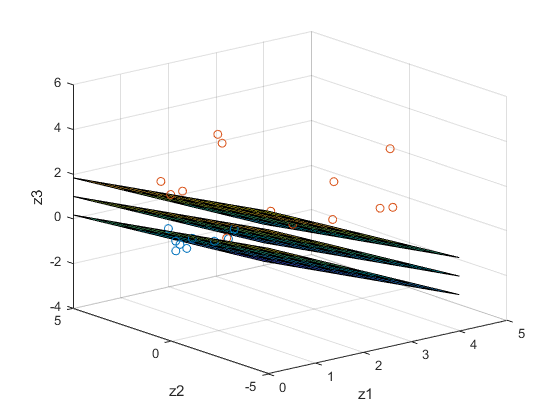

% plot the result
[z1,z2] = meshgrid(0:4,-5:5);
z3 = -x(3)/x(4)*z2 - x(2)/x(4)*z1 - x(1)/x(4);
surf(z1,z2,z3)
surf(z1,z2,z3-1/x(4))
surf(z1,z2,z3+1/x(4))

## Lecture 7: K-Means clustering

We will use mutual similarity of these group. 

### 1. K-Means impliementation

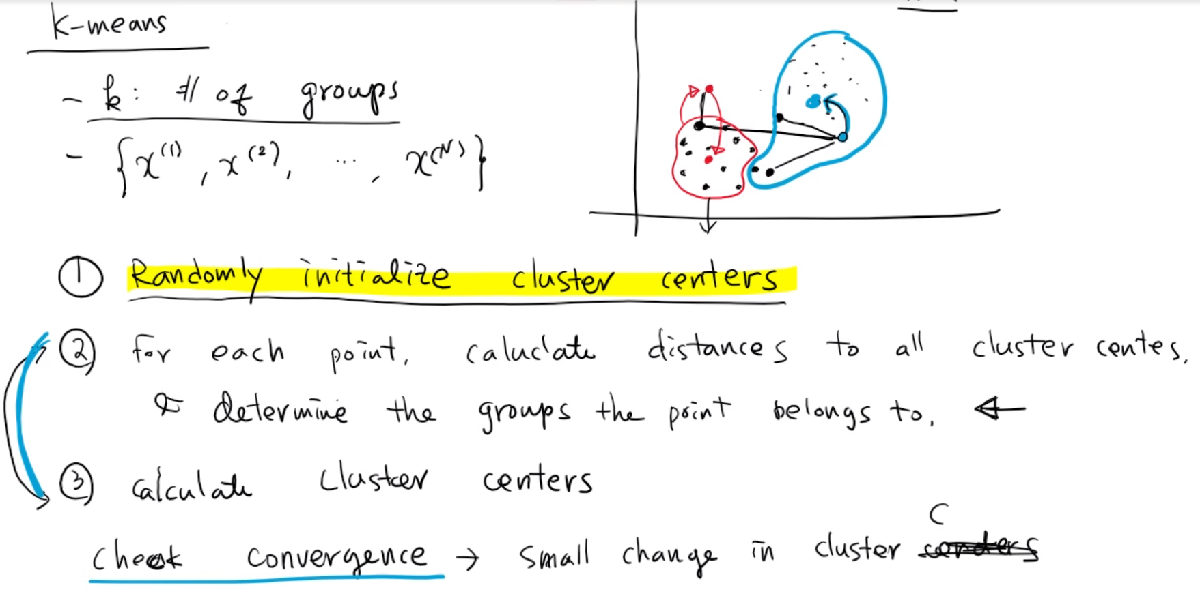

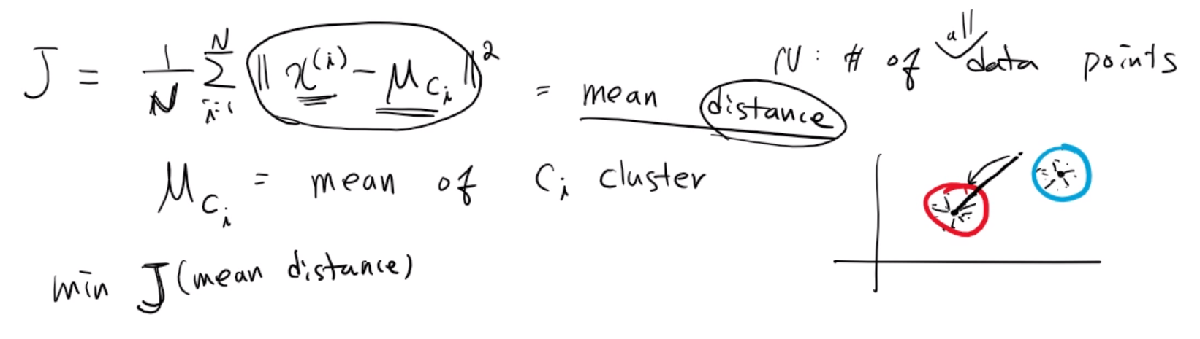

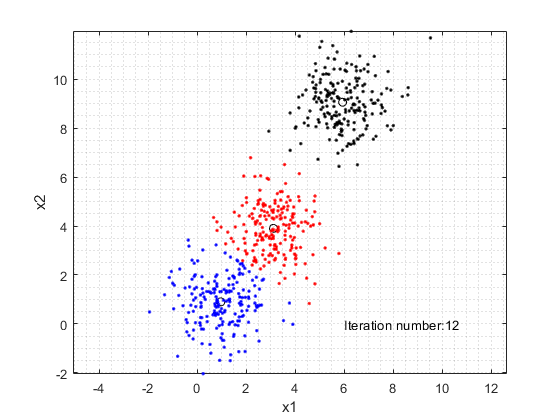

clearvars;close all;clc
% generate data
n = 200;
data1 = mvnrnd([1,1], eye(2), n);
% ->generate data with multivariate gaussian distribution
data2 = mvnrnd([3,4], eye(2), n);
data3 = mvnrnd([6,9], eye(2), n);

data_all = [data1; data2; data3];

plot(data_all(:,1), data_all(:,2), '.')
axis equal
xlabel('x1');
ylabel('x2');
grid minor
hold on

% k-means implementation
k = 3;
m = 3*randn(k,2) + 6; % initial mean

fig0 = plot(m(:,1), m(:,2), 'ko');
fig0.XDataSource = 'm(:,1)';
fig0.YDataSource = 'm(:,2)';
fig4 = text(0,10,'');

max_iter = 100;
mean_threshold = 0.01;
distance_m = zeros(k,1);
group_idx = zeros(size(data_all,1),1);
m_updated = zeros(size(m));

for i = 1:max_iter
    % for each data point, determine group index
    for j = 1:size(data_all,1)
        for s = 1:k
            distance_m(s) = norm(data_all(j,:) - m(s,:));
            % distance from cluster to this data point
        end
        [min_value, group_idx(j)] = min(distance_m);
    end
    for j = 1:k
        m_updated(j,:) = mean(data_all(group_idx == j,:));
    end
    if norm(m(:) - m_updated(:)) < mean_threshold
        m = m_updated;
        break;
    else
        m = m_updated;
        delete(fig4);
    end
    % Visualzation
    fig1 = plot(data_all(group_idx==1,1), data_all(group_idx ==1,2),'b.');
    fig1.XDataSource = 'data_all(group_idx==1,1)';
    fig1.YDataSource = 'data_all(group_idx==1,2)';

    fig2 = plot(data_all(group_idx==2,1), data_all(group_idx ==2,2),'r.');
    fig2.XDataSource = 'data_all(group_idx==2,1)';
    fig2.YDataSource = 'data_all(group_idx==2,2)';
    
    fig3 = plot(data_all(group_idx==3,1), data_all(group_idx ==3,2),'k.');
    fig3.XDataSource = 'data_all(group_idx==3,1)';
    fig3.YDataSource = 'data_all(group_idx==3,2)';
    
    fig4= text(6,0,['Iteration number:' num2str(i)]);
    refreshdata
    pause(1)

end

disp('Done')

Done


Caculate error

err = 0;
for i = 1:k 
    data_i = data_all(group_idx==i,:);
    for j = 1 size(data_i,1)
        err = err + norm(data_i(j,:) - m(i,:))^2;
    end
end

ans = 200

ans = 200

ans = 200

err = err/size(data_all,1)

err = 0.0241

### 2. Assignment 5

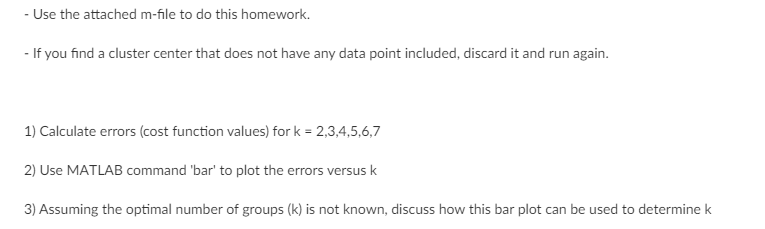

clearvars; clc; close all

MAX_K = 7;
MAX_ITERATION = 100;
MEAN_THRESHOLD = 1e-3;
line_colors = {'b.','r.','g.','m.','y.','c.','k.'};
n = 200;

data1 = mvnrnd([1,1], eye(2),n);
data2 = mvnrnd([3,4], eye(2),n);
data3 = mvnrnd([6,9], eye(2),n);

data_all = [data1; data2; data3];

% plot(data_all(:,1), data_all(:,2),'.');
% axis equal
% hold on

k_set = 2:1:7;
err_set = zeros(size(k_set));
add = 1;
for k = k_set
    disp(k)
    if k > MAX_K
        error('Use a smaller value for k.')
    end
    m = 3*randn(k,2) + 6;
    fig0 = plot(m(:,1),m(:,2),'ko');
    fig0.XDataSource = 'm(:,1)';
    fig0.YDataSource = 'm(:,2)';

    distance_mu = zeros(k,1);
    group_idx = zeros(size(data_all,1),1);
    m_updated = zeros(size(m));
    fig_info = text(0,10,'');
    fig_lines = cell(k,1);

    for i=1:MAX_ITERATION
        % for each data point, determine group index
        for j=1:size(data_all,1)
            for s=1:k
                distance_mu(s) = norm(data_all(j,:) - m(s,:));
            end
            [min_value, group_idx(j)] = min(distance_mu);
        end

        % for each group, determine mean values
        for j=1:k
            if isempty(find(group_idx == j,1))
                m_updated(j,:) = m(j,:);
            else
                m_updated(j,:) = mean(data_all(group_idx == j,:));
            end
        end

        % check the convergence
        if norm(m(:) - m_updated(:)) < MEAN_THRESHOLD
            m = m_updated;
            break;
        else
            m = m_updated;
%             delete(fig_info)
        end

        % draw
%         for j=1:k
%             idx = find(group_idx==j);
%             if isempty(idx)
%                 continue;
%             else
%                 fig_lines{j} = plot(data_all(idx,1),data_all(idx,2),line_colors{j});
%                 fig_lines{j}.XDataSource = ['data_all(group_idx==' num2str(j) ',1)'];
%                 fig_lines{j}.YDataSource = ['data_all(group_idx==' num2str(j) ',2)'];
%             end
%         end
%         fig_info = text(6,0,['Iteration number: ' num2str(i)]);
% 
%         refreshdata
%         pause(0.1)
%         close all
    end

    % error
    err = 0;
    for i=1:k
        data_i = data_all(group_idx==i,:);
        for j=1:size(data_i,1)
            err = err + norm(data_i(j,:)-m(i,:));
        end
    end
    err = err/size(data_all,1);
    
    err_set(add) = err;
    add = add + 1;
end

     2



     3



     4



     5



     6



     7



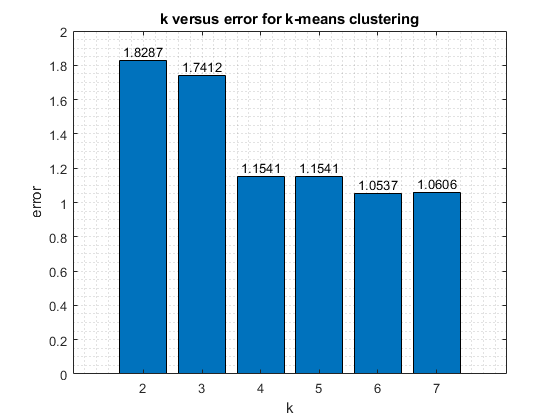

close all;

bar(err_set)
xlabel('k');
ylabel('error');
set(gca,'XTickLabel',2:1:7)
grid minor
text(1:length(err_set),err_set,num2str(err_set'),'vert','bottom','horiz','center'); 
title('k versus error for k-means clustering');

Base on the above figure 1, we can use **elbow method **to determine the reasonable number

of group. Meaning that, for the higher k, the error is decreased but somehow from k =3,4, the

error is decreased in slowly way. So, at these k, we can choose and assume this is the optimal

solution. From that, we can use this model to test on the test set and receive the appropriate results.

## Lecture 8: Monte carlo simulation - Principal component analysis 

### 1. Monte carlo simulation

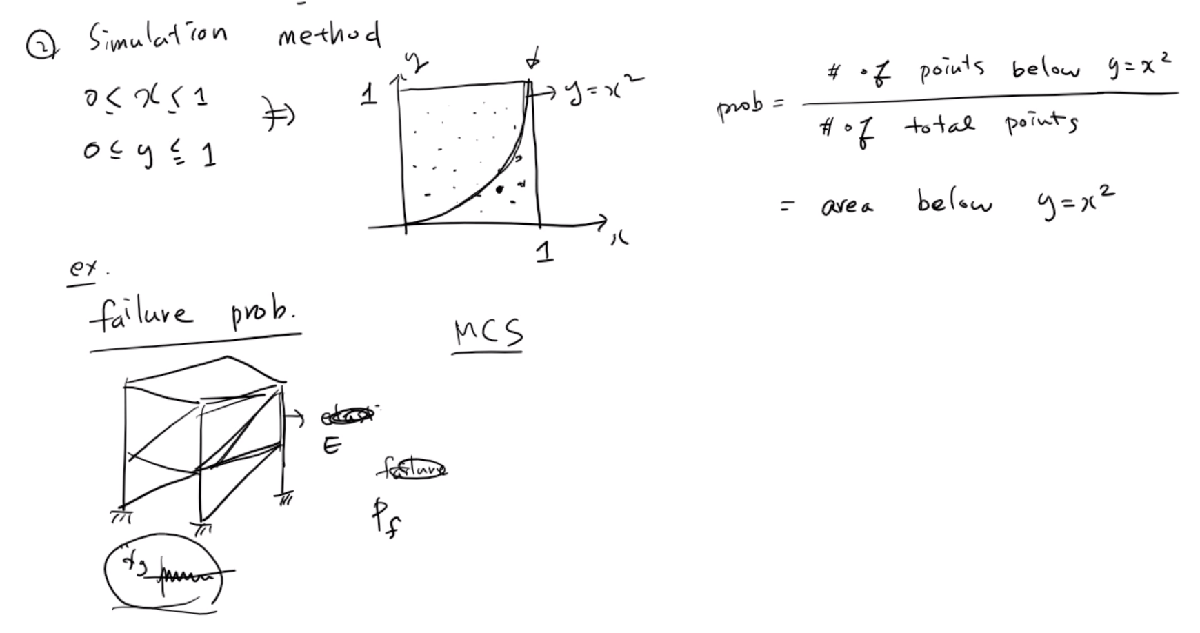

clearvars; close all;clc;
%% caculate circle area
n = 10000; %  so luong cot trong ma tran ngau nhien
a = rand(2,n);a = a*2-1; % tao ma tran ngau nhien voi 2 hang, n cot, cho chay tu khoang -1 den 1
x=a(1,:); y = a(2,:); % gan x voi hang 1, va y voi hang 2
plot(x,y,'ro');
hold on
ind = find(x.^2 + y.^2 <=1); cn = length(ind); % ham length lay tong cac so nam trong duong tron
area = cn/n*4

area = 3.1364

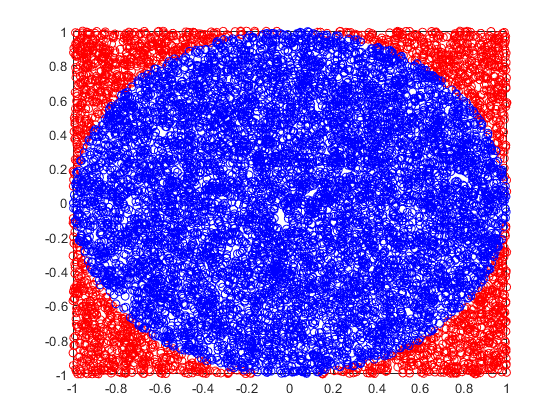

plot(x(ind),y(ind),'bo')

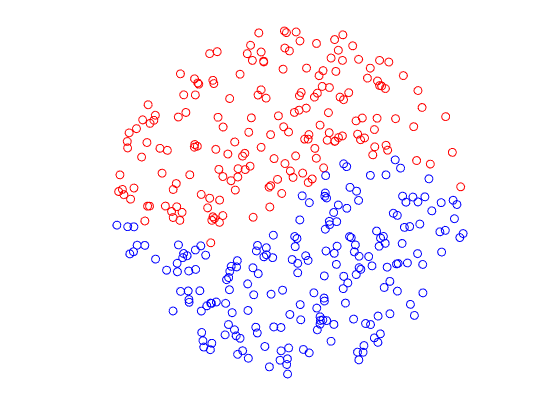

%% draw korea national flag 
clearvars; close all;clc;
n = 500;
a = rand(2,n); a =a*2 -1;
x=a(1,:); y = a(2,:); 
ind = find(x.^2 + y.^2 <=1 &y>0.25*sin(x*pi)); %condition above and below y =0 line
plot(x(ind),y(ind),'ro');
hold on;
ind = find(x.^2 + y.^2 <=1 &y<0.25*sin(x*pi)) ;
plot(x(ind),y(ind),'bo');
axis off; axis image 

### 2. Princial component analysis

clear all;close all;clc;


n = 10000;
mu = [0 0];
sigma = [3 1.5;
        1.5 1];
X = mvnrnd(mu, sigma, n);

plot(X(:,1), X(:,2), '.')
grid minor
hold on 

xlabel('x1');
ylabel('x2');

S = (1/n)*X'*X;

% u: eigen vector
% d: eigen values 
[u,d] = eig(S)

u =     0.4731   -0.8810
   -0.8810   -0.4731


d =     0.1939         0
         0    3.7754


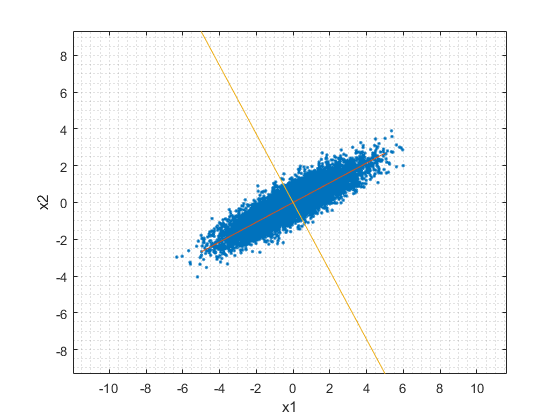


u1 = u(:,2); % first principal component
u2 = u(:,1);

plot([-5 5],[-5 5]*(-1)*u(1,1)/u(2,1))
plot([-5 5],[-5 5]*(-1)*u(1,2)/u(2,2))
axis equal

### 3. Assignment 6

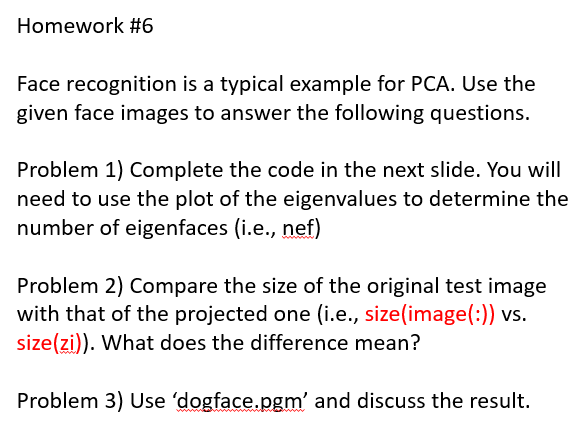

clearvars;close all;clc

path_data = 'E:/10. Course Work/4. Spring 2020/1. AI-based course/Code/Review/A6';
cd(path_data);

filelist = ls;
filelist = filelist(filelist(:,1) == 's',:);
n_images = size(filelist,1);
 
X = zeros(n_images,56*46);
for i=1:n_images
    img = imread(filelist(i,:));
    img = imresize(img, 0.5);
    X(i,:) = img(:)';
end
 
mu = mean(X);
X = X - mu;
S =  (1/n_images)*X'*X;
 
[u,d] = eig(S);
d = abs(diag(d));
[d, idx] = sort(d,'descend');
u = u(:,idx);
 
figure; 
disp('Eigen values')

Eigen values


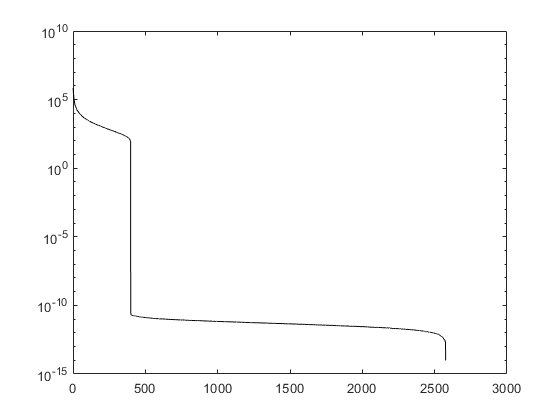

semilogy(d,'k')


% 
figure
disp('Data set')

Data set


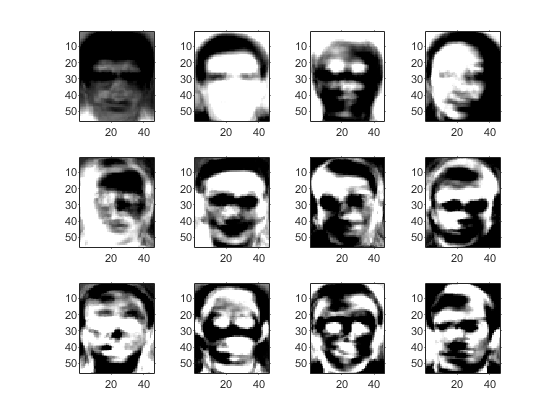

for i=1:12
    u1_img = 10000*u(:,i) + mu';
    u1_img = reshape(u1_img,[56,46]);
    u1_img = uint8(u1_img);
    subplot(3,4,i)
    imshow(u1_img)
    axis on
end

%  
% %% face reconstruction
% close all
nef = 401;
img = imread('test_image.pgm');
img = imresize(img,[56, 46]);
img_vector = double(img(:));

zi = u(:,1:nef)'*img_vector;


face5_reconstructed = u(:,1:nef) * zi + mu';
face5_reconstructed = reshape(face5_reconstructed,[56,46]);
figure;
disp('Face reconstruction')

Face reconstruction


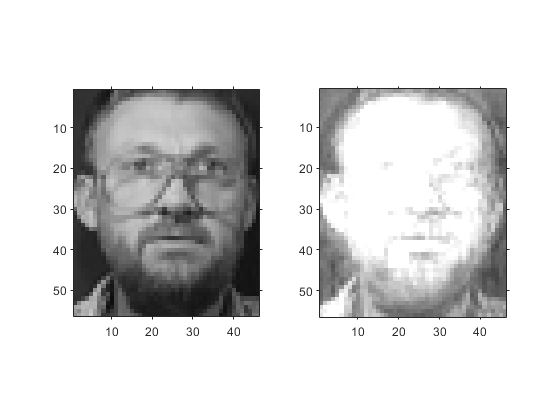

subplot(1,2,1); imshow(img)
axis on
subplot(1,2,2); imshow(uint8(face5_reconstructed))
axis on

size(img(:));
size(zi);

% dog face
nef = 399;
img = imread('dogface.pgm');
img = imresize(img,[56, 46]);
img_vector = double(img(:));

zi = u(:,1:nef)'*img_vector;


face5_reconstructed = u(:,1:nef) * zi + mu';
face5_reconstructed = reshape(face5_reconstructed,[56,46]);
figure;
disp('Dogface reconstruction')

Dogface reconstruction


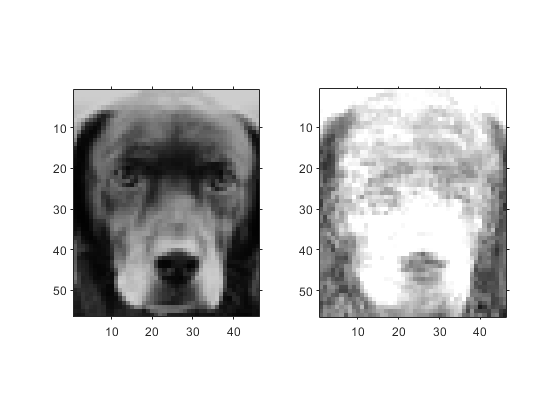

subplot(1,2,1); imshow(img)
axis on
subplot(1,2,2); imshow(uint8(face5_reconstructed))
axis on

Because of vector u contained the feature from 399 human faces, so when we try the test image

with the dog face. We can see our result showed the reconstructed image similar with human

face. Meaning that, the eigen vectors that we extracted from sample data, can only work well for

human faces. For the dog face, we need create another eigen vector with the sample data

contain dog faces.  

## Lecture 9: Fisher Discriminant analysis

### 1. FDA 

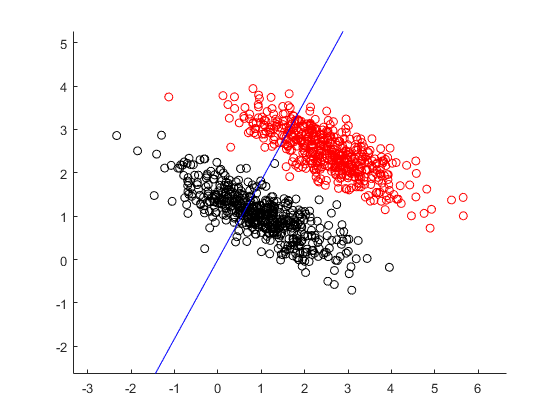

clearvars; close all;clc;
% generate data
n0 = 500; %class 0, 500 data points
n1 = 500;

mu = [0 0];
sigma = [0.9 -0.4
        -0.4 0.3];
    
x0 = mvnrnd(mu,sigma,n0)' + 2.5*ones(2,n0);
x1 = mvnrnd(mu,sigma,n1)' + 1*ones(2,n1);

% mean along row 
mu0 = mean(x0,2);
mu1 = mean(x1,2);

% x0 - repmat(mu0,1,n0) -> zero mean technque
S0 = 1/(n0-1)*(x0 - repmat(mu0,1,n0))*(x0 - repmat(mu0,1,n0))';
S1 = 1/(n1-1)*(x1 - repmat(mu1,1,n1))*(x1 - repmat(mu1,1,n1))';

k = 1;
w = k*inv(n0*S0 + n1*S1)*( mu0 - mu1);
% make w become the unit vector.
w = w/norm(w);

figure;
scatter(x0(1,:), x0(2,:), 'ro');
hold on 
scatter(x1(1,:), x1(2,:),'ko');

z = -3:0.1:6;
wline = w*z;
hold on 
plot(wline(1,:), wline(2,:),'b-')
axis equal

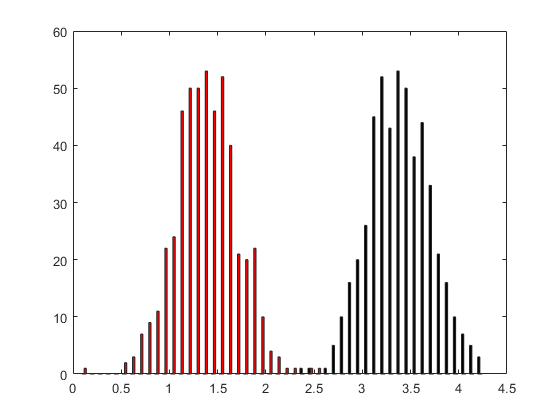


figure;
y0 = x0'*w;
y1 = x1'*w;
hist([y0 y1], 50)
h = findobj(gca,'type','patch');
h(1).FaceColor = 'r';
h(2).FaceColor = 'k';

### 2. Neural network

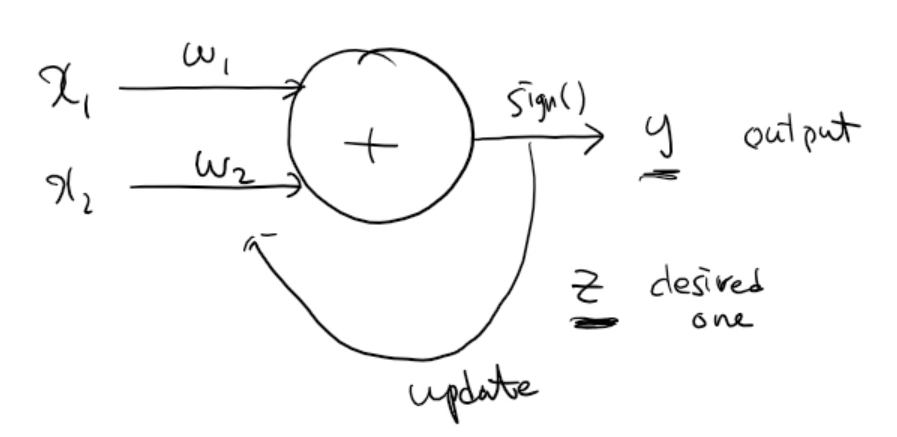

First, working with XOR problem.

### 3. Assignment 7

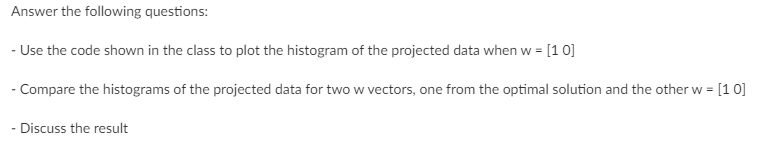

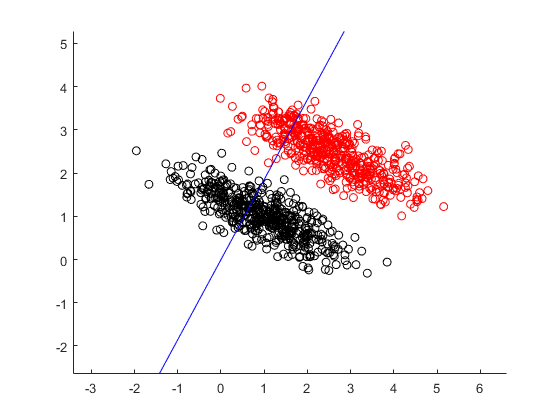

clearvars; close all;clc;
% generate data
n0 = 500; %class 0, 500 data points
n1 = 500;

mu = [0 0];
sigma = [0.9 -0.4
        -0.4 0.3];
    
x0 = mvnrnd(mu,sigma,n0)' + 2.5*ones(2,n0);
x1 = mvnrnd(mu,sigma,n1)' + 1*ones(2,n1);

% mean along row 
mu0 = mean(x0,2);
mu1 = mean(x1,2);

% x0 - repmat(mu0,1,n0) -> zero mean technque
S0 = 1/(n0-1)*(x0 - repmat(mu0,1,n0))*(x0 - repmat(mu0,1,n0))';
S1 = 1/(n1-1)*(x1 - repmat(mu1,1,n1))*(x1 - repmat(mu1,1,n1))';

k = 1;
w = k*inv(n0*S0 + n1*S1)*( mu0 - mu1);
% make w become the unit vector.
w = w/norm(w);

figure;
scatter(x0(1,:), x0(2,:), 'ro');
hold on 
scatter(x1(1,:), x1(2,:),'ko');

z = -3:0.1:6;
wline = w*z;
hold on 
plot(wline(1,:), wline(2,:),'b-')
axis equal

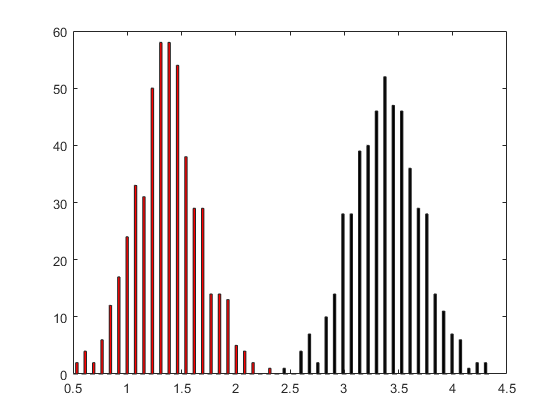


figure;
y0 = x0'*w;
y1 = x1'*w;
hist([y0 y1], 50)
h = findobj(gca,'type','patch');
h(1).FaceColor = 'r';
h(2).FaceColor = 'k';


w = [1 0]'

w =      1
     0


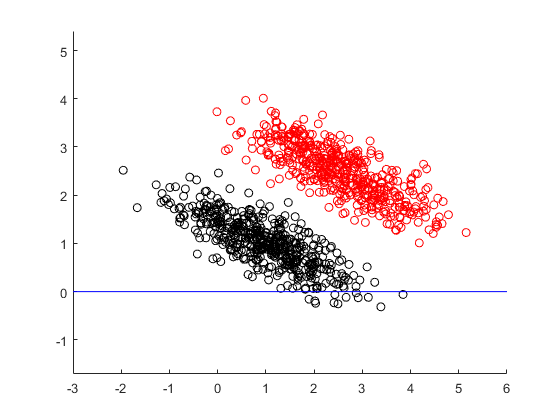

% make w become the unit vector.
w = w/norm(w);

figure;
scatter(x0(1,:), x0(2,:), 'ro');
hold on 
scatter(x1(1,:), x1(2,:),'ko');

z = -3:0.1:6;
wline = w*z;
hold on 
plot(wline(1,:), wline(2,:),'b-')
axis equal

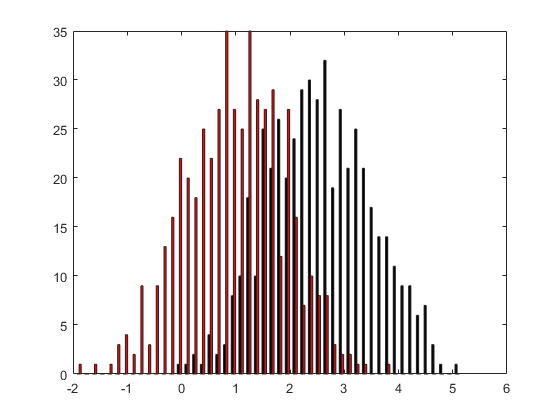


figure;
y0 = x0'*w;
y1 = x1'*w;
hist([y0 y1], 50)
h = findobj(gca,'type','patch');
h(1).FaceColor = 'r';
h(2).FaceColor = 'k';

## Lecture 10: Artifical neural network

### 1. XOR Problem

### 2. Assignment 8

% function z = ANN(x1,x2)
%     y1 = sign(x1 + x2 + 0.5);
%     y2 = sign(x1 + x2 - 1.5);
%     z = sign(0.7*y1 + (-0.4)*y2 -1);
% end

## Lecture 11: Artifical neural network (Cont.)

### 1. Implementation back propagation

### 2. Assignment 9

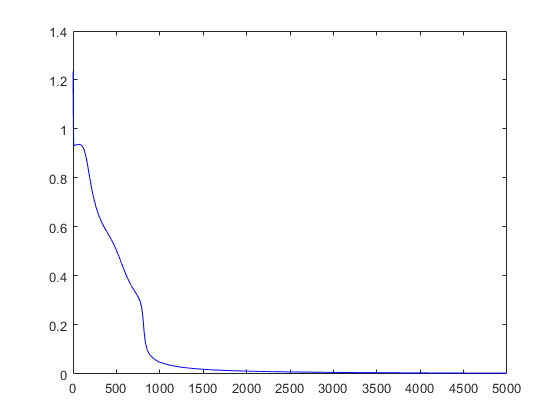

data_x = [0 0 1 1;
        0 1 0 1];
data_t = [0 1 1 0];

% we have 2 inputs and 4 hidden unit, 1 hidden layer.
wji = 2*rand(4,2) - 1;
wkj = 2*rand(1,4) - 1;

error_s = [];
for epoch = 1:5000
    [wji, wkj, error] = backpropagation(wji, wkj, data_x, data_t);
    error_s = [error_s, error];
end

plot(error_s,'b')

% we assume that our wji and wkj ara reasonably good numbers
for i = 1:4
    % feed forward
    x = data_x(:,i);
    y = sigmoid_func(wji*x);
    z = sigmoid_func(wkj*y)
    
end

z = 0.0321

z = 0.9705

z = 0.9743

z = 0.0288

## Lecture 12: Artifical neural network (Cont.) + CNN

### 1. Multi-class

### 2. Convolutional neural network

Introduce about 1D convolution.

clearvars;close all;clc

### 3. Assignment 10

clearvars; clc; close all

numbers = zeros(5,5,10);
numbers(:,:,1) = [0 1 1 0 0
                  0 0 1 0 0
                  0 0 1 0 0
                  0 0 1 0 0
                  0 1 1 1 0];
numbers(:,:,2) = [1 1 1 1 0
                  0 0 0 0 1
                  0 1 1 1 0
                  1 0 0 0 0
                  1 1 1 1 1];
numbers(:,:,3) = [1 1 1 1 0
                  0 0 0 0 1
                  0 1 1 1 0
                  0 0 0 0 1
                  1 1 1 1 0];
numbers(:,:,4) = [0 0 0 1 0
                  0 0 1 1 0
                  0 1 0 1 0
                  1 1 1 1 1
                  0 0 0 1 0];
numbers(:,:,5) = [1 1 1 1 1
                  1 0 0 0 0
                  1 1 1 1 0
                  0 0 0 0 1
                  1 1 1 1 0];
              
numbers(:,:,6) = [0 1 1 1 0
                  1 0 0 0 1
                  1 0 0 0 1
                  1 0 0 0 1
                  0 1 1 1 0];
numbers(:,:,7) = [0 1 1 1 1
                  1 0 0 0 0
                  1 1 1 1 0
                  1 0 0 0 1
                  0 1 1 1 0];
numbers(:,:,8) = [1 1 1 1 1
                  0 0 0 1 0
                  0 0 1 0 0
                  0 1 0 0 0
                  1 0 0 0 0]; 
numbers(:,:,9) = [0 1 1 1 0
                  1 0 0 0 1
                  0 1 1 1 0
                  1 0 0 0 1
                  0 1 1 1 0];
numbers(:,:,10) =[0 1 1 0 0
                  1 0 0 0 1
                  0 1 1 1 1
                  0 0 0 0 1
                  1 1 1 1 0];
              
data_x = zeros(25,10);
for idx=1:10
    tmp = numbers(:,:,idx);
    data_x(:,idx) = tmp(:);
end
data_t = eye(10);

% initial random values assigned to weights
wji = 2*rand(50,25) - 1;
wkj = 2*rand(10,50) - 1;

for epoch=1:10000
    [wji, wkj] = backpropagation_number(wji,wkj,data_x,data_t);
end

% feedforward
for idx=1:10
    x = data_x(:,idx);
    y = sigmoid_func(wji*x);
    z = softmax_func(wkj*y)
end

z =     0.9966
    0.0000
    0.0000
    0.0000
    0.0000
    0.0008
    0.0014
    0.0000
    0.0008
    0.0004


z =     0.0000
    0.9958
    0.0025
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0011
    0.0005


z =     0.0000
    0.0017
    0.9949
    0.0000
    0.0015
    0.0000
    0.0000
    0.0000
    0.0006
    0.0013


z =     0.0003
    0.0009
    0.0000
    0.9966
    0.0000
    0.0001
    0.0008
    0.0000
    0.0012
    0.0000


z =     0.0000
    0.0001
    0.0020
    0.0000
    0.9952
    0.0000
    0.0018
    0.0002
    0.0000
    0.0007


z =     0.0003
    0.0005
    0.0000
    0.0000
    0.0000
    0.9965
    0.0012
    0.0000
    0.0011
    0.0004


z =     0.0003
    0.0004
    0.0000
    0.0000
    0.0022
    0.0002
    0.9953
    0.0000
    0.0013
    0.0003


z =     0.0000
    0.0008
    0.0000
    0.0000
    0.0021
    0.0000
    0.0000
    0.9965
    0.0000
    0.0005


z =     0.0000
    0.0011
    0.0008
    0.0000
    0.0000
    0.0002
    0.0007
    0.0000
    0.9956
    0.0015


## Lecture 13: Convolutional neural network

### **1. Assignment 11**

#### **1. Crop and process data**

path_data = 'E:/10. Course Work/4. Spring 2020/1. AI-based course/Code/CNN_11';
cd(path_data)

% 1 67 94
% 2 300 94
% 3 67 334
% 4 300 334
x_f = 67;
y_f = 94;
k_train = 1;
k_test = 1;
dx = 233;
dy = 243;

num_train = 130;
data_train= zeros(28,28,num_train);
num_test = 110;
data_test= zeros(28,28,num_test);
img_num = 1;
path_save = 'E:/10. Course Work/4. Spring 2020/1. AI-based course/Code/CNN_11/Dataset/%g';

for data_num = 1:2
    digit_num = 0;
    if data_num == 1 
        row_num = 13;
    elseif data_num == 2
        row_num = 11;
    path_root = 'E:/10. Course Work/4. Spring 2020/1. AI-based course/Code/CNN_11';
    cd(path_root);
    end
    data_set = imread(sprintf('Scan%g.jpeg',data_num));
    fprintf('PROCESSING DATA NUM: %g',data_num);
    
    figure;
    imshow(data_set);
    axis on
    grid minor
    hold on
    for row = x_f:dx:dx*10
        for col = y_f:dy:dy*row_num
            crop_data = data_set(col:col+dx,row:row+dy,:);
            rectangle('Position',[row col dx dy],'EdgeColor','b')
            convert_gray = rgb2gray(crop_data);
            % Resize
            resized_convert_gray = imresize(convert_gray,[28 28]);
            path_save_num = sprintf(path_save,digit_num);
            cd(path_save_num)
            
%             file_name = sprintf('img%g.png',img_num);
%             img_num = img_num+1;
%             imwrite(uint8(resized_convert_gray), file_name)
            
            if data_num == 1
                data_train(:,:,k_train) = resized_convert_gray;
                k_train = k_train +1;
            elseif data_num == 2
                data_test(:,:,k_test) = resized_convert_gray;
                k_test = k_test +1;
            end
        end
        digit_num = digit_num+1;
    end
    disp('Done');
end

#### **2. CNN implementation**

clearvars; clc; close all

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DaiDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');


figure;
perm = randperm(130,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

labelCount = countEachLabel(imds)

img = readimage(imds,1);
size(img)

numTrainFiles = 23;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',100, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',1, ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)


mine = imread(imds.Files{100});
figure; imshow(mine)
classify(net,mine)